clear

# Biharmonic operator on a disk

N = 35;
M = 20;
[r, a, rr, aa, I, D1r, D2r, D3r, D4r, D2a, D4a, bc, bcinv] = get_operators(N, M);

Biharmonic operator

[r2, I, D1r, D2r, D3r, D4r] = get_factored_operators(rr, I, D1r, D2r, D3r, D4r);
L = D4r + 2*D2r*D2a./rr.^2 + D4a./rr.^4 + 2*D3r./rr - 2*D1r*D2a./rr.^3 - D2r./rr.^2 + 4*D2a./rr.^4 + D1r./rr.^3;
L = L * diag(1./r2);
% boundary condition
L = bc(L);

Compute eigenvalues

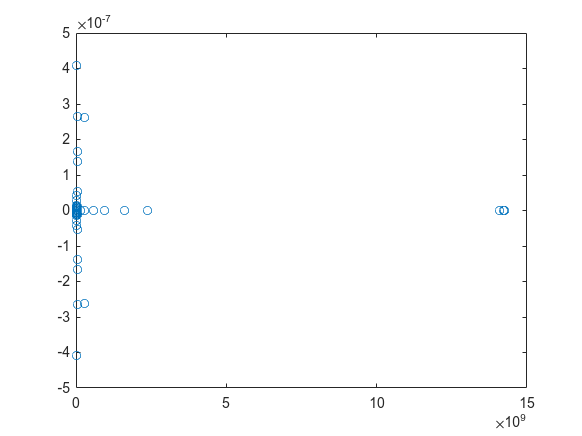

[V, lam] = eig(L); 
lam = diag(lam); 
[lam,ii] = sort(lam);
V = V(:,ii);
V = bcinv(V);
V = V.*r2;
plot(lam, 'o')

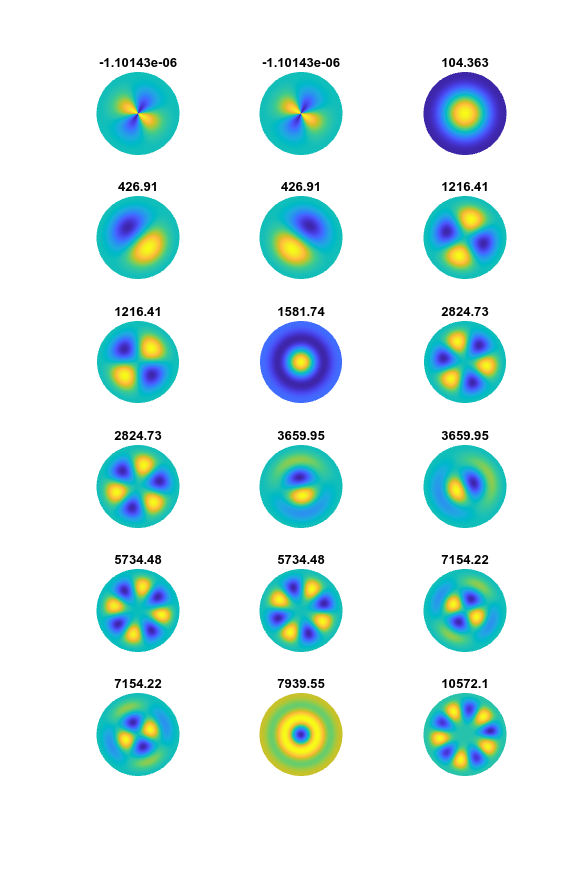

fig = figure;
for i = 1:18
    subplot(6,3,i)
    my_plot(r, a, V(:,i))
    axis off
    view([0,90])
    title(lam(i))
end
fig.Position(4) = 2*fig.Position(4);

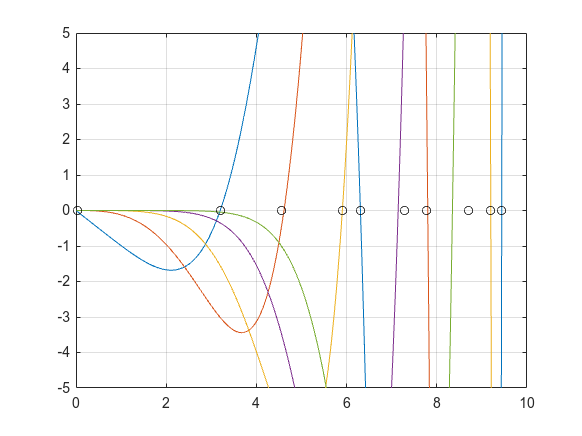

% The evalues of the (m,n) mode are the n-th root of the m-th order equation
% Lindsay2015 Proc. R. Soc. A 471: 20150474 (Equation 4.5b)
fun = @(m,z) 0.5*(besselj(m-1,z)-besselj(m+1,z)) .* besseli(m,z) - (besseli(m-1,z)-m*besseli(m,z)./z) .* besselj(m,z);

figure
z = 0:0.01:10;
for m = 0:4    
    plot(z, fun(m,z))
    hold on
end
plot(real(lam(1:18).^0.25), zeros(1,18), 'ko')
hold off
grid on
ylim([-5,5])
xlim([0,10])